# Read Hexadecimal and Binary Numbers from File

You can read hexadecimal and binary numbers from a file and store them as numeric variables in a table. The `readtable` function automatically reads hexadecimal and binary numbers when they include the `0x` and `0b` prefixes respectively. The numeric values are stored using integer data types. You can also use import options to read such numbers when they do not have prefixes.

Preview the `hexAndBinary.txt` file in a text editor. It has columns of hexadecimal and binary numbers with prefixes, and one column without.

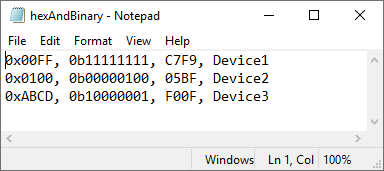

Read the file using `readtable`. The function detects the numbers with `0x` and `0b` prefixes and stores them as integers. The third column does not have prefixes so its values are treated as text.

T = readtable('hexAndBinary.txt')

The `readtable` function stores the numeric values in different integer classes (`uint16` and `uint8`) because `T.Var1` has a value that requires more than 8 bits of storage.

class(T.Var1)
class(T.Var2)

To specify the data types for storing the numeric values imported from hexadecimal and binary numbers, use the `'HexType'` and `'BinaryType'` name-value pair arguments. Store the values as signed 32-bit integers.

T = readtable('hexAndBinary.txt','HexType','int32','BinaryType','int32');
class(T.Var1)
class(T.Var2)

You can use import options to detect hexadecimal and binary numbers without prefixes, and specify storage for them. Create an import options object for `hexAndBinary.txt`.

opts = detectImportOptions('hexAndBinary.txt')

To specify that the third column should be imported as hexadecimal values, despite the lack of a prefix, use the `setvaropts` function to modify the variable type for the third variable of the table. Set the variable type to `int32`.

opts = setvaropts(opts,3,'NumberSystem','hex','Type','int32')

Read the file and import the third column as numeric values, not text.

T = readtable('hexAndBinary.txt',opts)

*Copyright 2019 The MathWorks, Inc.*